% Exercise 2
% Q1 & Q2: Class parameters from Exercise 1

% Baseline means and covariances
mu_a = [0, 4, 7];
mu_b = [10, 5, 5];
mu_c = [-2, -5, -5];

covm_a = [6.5 2.1651 1.25;
    2.1651 5.125 2.3816;
    1.25 2.3816 2.375];
covm_b = [3.0184 0.4331 -1.4481;
    0.4331 0.9436 -0.6456;
    -1.4481 -0.6456 1.288];
covm_c = [6.8928 -1.375 3.1945;
    -1.375 3.3572 0.6945;
    3.1945 0.6945 3.75];

% Grid parameters for boundary computation
Vaxis = [-15, 15];
Num = 200; % 200^3 regular grid points


Q2: We load the plotting functions from Activity 1 and play with the means and covariances of the three classes, assessing how they affect the class boundaries.

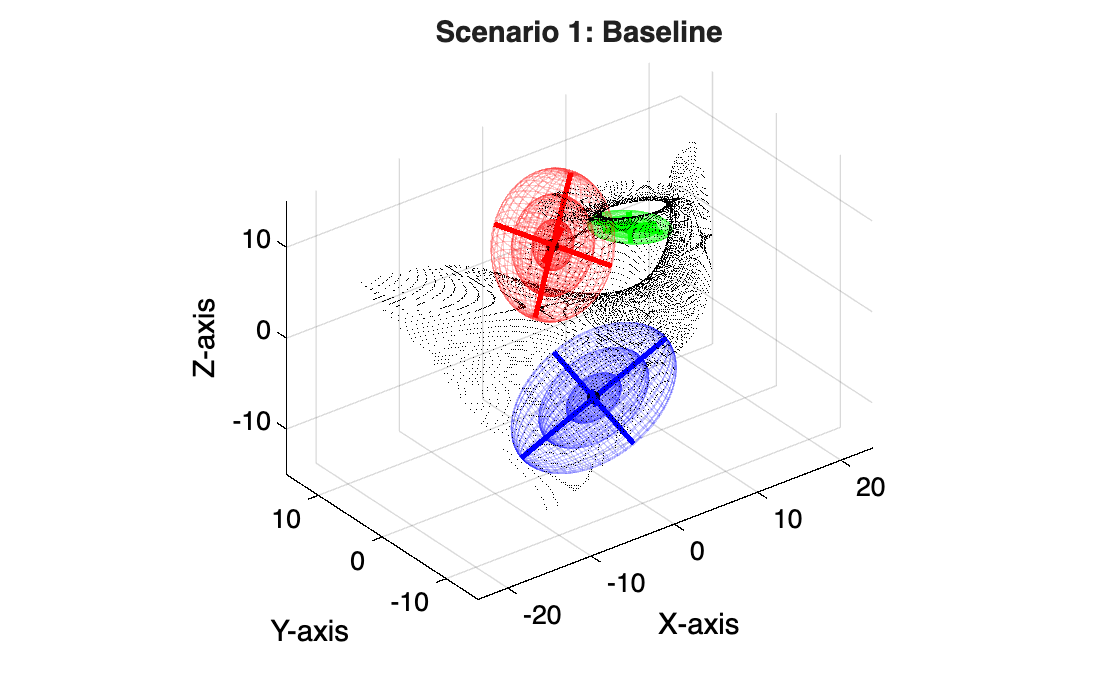

% Scenario 1: Baseline - original means and covariances from Exercise 1
plotScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, 'Scenario 1: Baseline', Vaxis, Num);


function plotClassEllipsoids(mu, covm, color)
    % 1. Get eigenvalues (D) and eigenvectors (V)
    [V, D] = eig(covm);
    
    % The lengths of the semi-axes are the square roots of the eigenvalues
    % (which represent 1 standard deviation along the principal axes)
    radii_1std = sqrt(diag(D))';
    
    % Define the standard deviations we want to plot
    stdDevs = [1, 2, 3];
    
    % Loop through 1, 2, and 3 standard deviations
    for sd = stdDevs
        % Scale the base radii by the standard deviation level
        current_radii = radii_1std * sd;
        
        % Generate a standard axis-aligned ellipsoid at the origin
        % syntax: ellipsoid(xc, yc, zc, xr, yr, zr, n)
        [X, Y, Z] = ellipsoid(0, 0, 0, current_radii(1), current_radii(2), current_radii(3), 30);
        
        % Rotate and translate the ellipsoid points
        % Pack points into an N x 3 matrix
        pts = [X(:), Y(:), Z(:)];
        
        % Apply rotation (V) and shift to the mean (mu)
        rotated_pts = (pts * V') + mu;
        
        % Reshape back into surface grids for plotting
        X_rot = reshape(rotated_pts(:,1), size(X));
        Y_rot = reshape(rotated_pts(:,2), size(Y));
        Z_rot = reshape(rotated_pts(:,3), size(Z));
        
        % Plot the ellipsoid surface with transparency (Alpha)
        mesh(X_rot, Y_rot, Z_rot, 'FaceColor', 'none', 'EdgeColor', color, 'EdgeAlpha', 0.2);
    end
    
    % 2. Plot the Principal Axes (drawn out to 3 standard deviations)
    for d = 1:3
        % Direction vector of the principal axis
        axis_direction = V(:, d)'; 
        % Half-length of the axis at 3 standard deviations
        half_length = radii_1std(d) * 3; 
        
        % Calculate start and end points for the line
        p_start = mu - half_length * axis_direction;
        p_end = mu + half_length * axis_direction;
        
        % Draw the principal axis line using matlab's line() function
        line([p_start(1), p_end(1)], ...
             [p_start(2), p_end(2)], ...
             [p_start(3), p_end(3)], ...
             'Color', color, 'LineWidth', 2);
    end
    
    % Plot the center mean point
    plot3(mu(1), mu(2), mu(3), 'k.', 'MarkerSize', 15);
end

% Compute Bayes decision boundary points for three Gaussian classes
function [bAB, bAC, bCB] = computeBoundaries(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, Vaxis, Num)
    grid_points = vol3D(Vaxis, Num);

    covm_a_inv = inv(covm_a);
    covm_b_inv = inv(covm_b);
    covm_c_inv = inv(covm_c);

    covm_a_det = det(covm_a);
    covm_b_det = det(covm_b);
    covm_c_det = det(covm_c);

    cp_a = grid_points - mu_a;
    cp_b = grid_points - mu_b;
    cp_c = grid_points - mu_c;

    % Bayesian discriminant scores (equal priors)
    g_a = -0.5 * sum((cp_a * covm_a_inv) .* cp_a, 2) - 0.5 * log(covm_a_det) + log(1/3);
    g_b = -0.5 * sum((cp_b * covm_b_inv) .* cp_b, 2) - 0.5 * log(covm_b_det) + log(1/3);
    g_c = -0.5 * sum((cp_c * covm_c_inv) .* cp_c, 2) - 0.5 * log(covm_c_det) + log(1/3);

    epsilon = 0.05;
    bAB = grid_points((abs(g_a - g_b) < epsilon) & (g_a > g_c) & (g_b > g_c), :);
    bAC = grid_points((abs(g_a - g_c) < epsilon) & (g_a > g_b) & (g_c > g_b), :);
    bCB = grid_points((abs(g_b - g_c) < epsilon) & (g_b > g_a) & (g_c > g_a), :);
end

% Compute boundaries and produce a labelled 3-D plot
function plotScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, titleStr, Vaxis, Num)
    [bAB, bAC, bCB] = computeBoundaries(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, Vaxis, Num);
    colors = {'r', 'g', 'b'};
    figure;
    set(gcf, 'Color', 'w');
    clf; hold on; grid on; axis equal; view(3);
    % Force white axes regardless of MATLAB theme
    set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k');
    plotClassEllipsoids(mu_a, covm_a, colors{1});
    plotClassEllipsoids(mu_b, covm_b, colors{2});
    plotClassEllipsoids(mu_c, covm_c, colors{3});
    plot3(bAB(:,1), bAB(:,2), bAB(:,3), 'k.', 'MarkerSize', 1);
    plot3(bAC(:,1), bAC(:,2), bAC(:,3), 'k.', 'MarkerSize', 1);
    plot3(bCB(:,1), bCB(:,2), bCB(:,3), 'k.', 'MarkerSize', 1);
    title(titleStr);
    xlabel('X-axis'); ylabel('Y-axis'); zlabel('Z-axis');
    hold off;
end

Next we experiment with different combinations of mu and covariance to see how the class boundaries change.

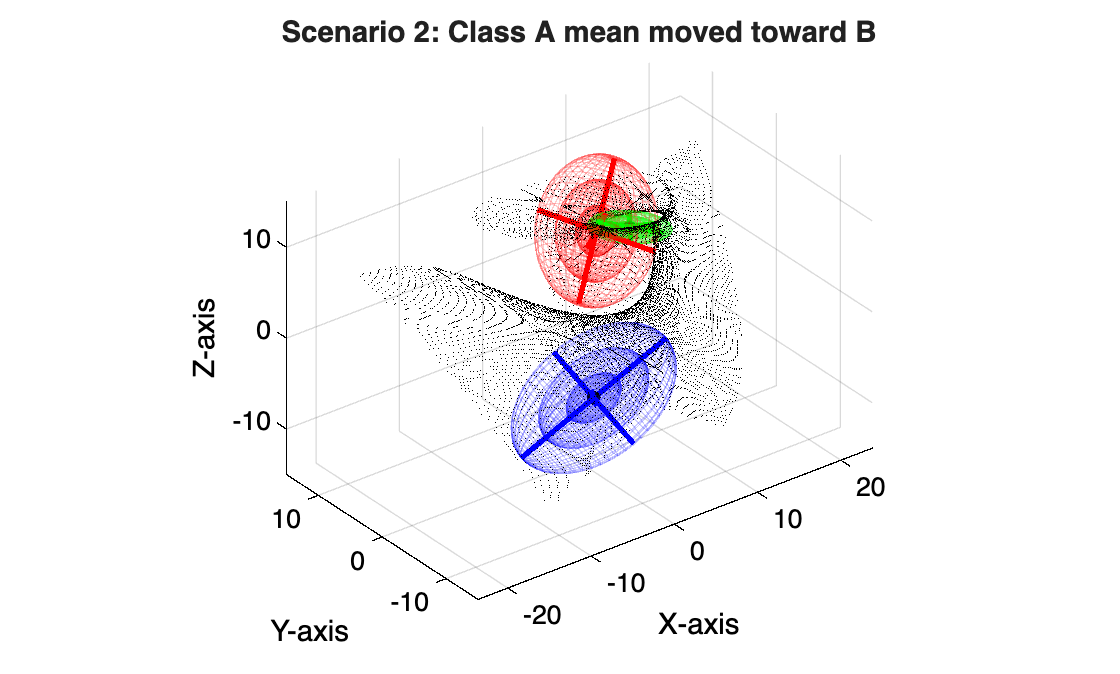

% Scenario 2: Move class A closer to class B (means approach each other)
mu_a2 = [6, 5, 6];
plotScenario(mu_a2, covm_a, mu_b, covm_b, mu_c, covm_c, 'Scenario 2: Class A mean moved toward B', Vaxis, Num);

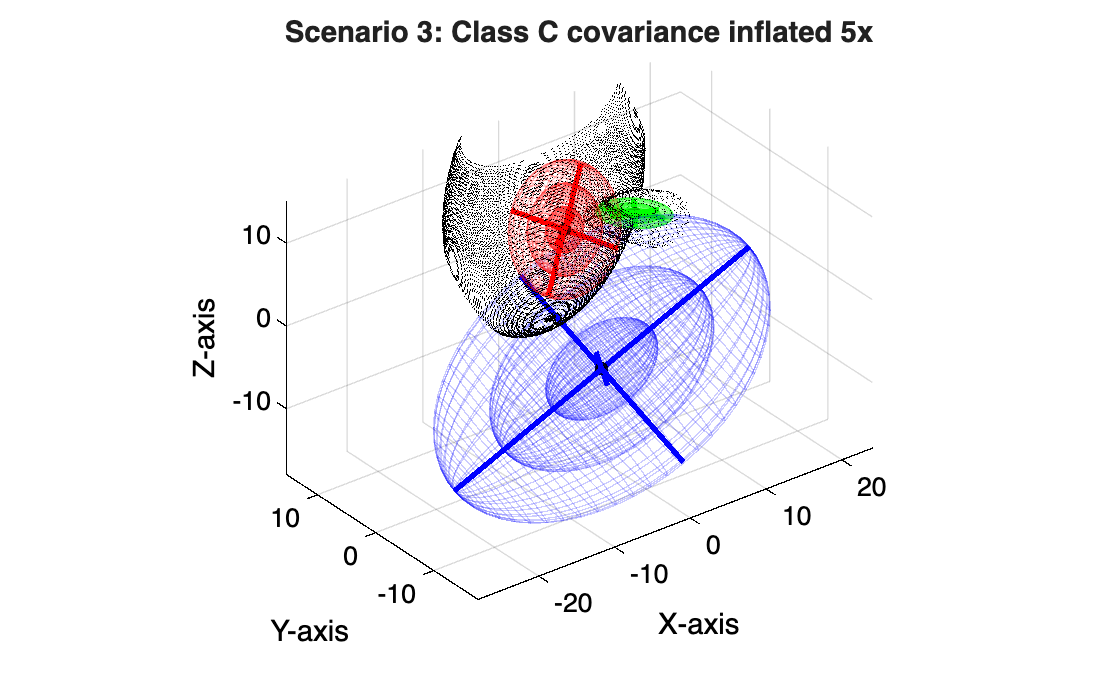


% Scenario 3: Inflate class C covariance (spreads C's distribution)
covm_c3 = covm_c * 5;
plotScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c3, 'Scenario 3: Class C covariance inflated 5x', Vaxis, Num);

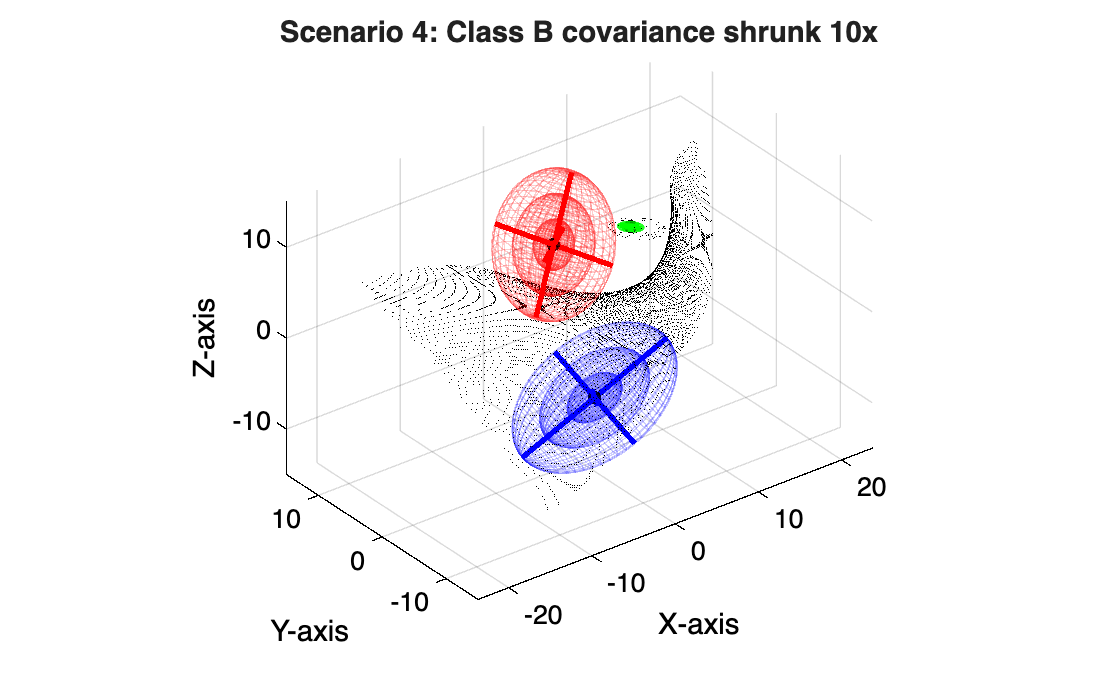


% Scenario 4: Shrink class B covariance
covm_b4 = covm_b * 0.1;
plotScenario(mu_a, covm_a, mu_b, covm_b4, mu_c, covm_c, 'Scenario 4: Class B covariance shrunk 10x', Vaxis, Num);

Q3: We identify which class covariance produces the most sensitive decision boundaries by looking at the eigenvalue ratios. Class B has a 16:1 max/min eigenvalue ratio - the largest of the three classes. Its smallest eigenvalue (0.25) causes high sensitivity. This is because the Bayesian decision boundaries depend on the inverse of the covariance, whose eigenvalues are the reciprocals of the covariance's eigenvalues. This in turn means that a small change to a small eigenvalue causes a disproportionately large change in the inverse of the covariance, which directly drives the discriminant function and hence the decision boundary shape. We demonstrate this with two examples: nudging that eigenvalue up and down by 50%. To illustrate: applying a small absolute change to the smallest eigenvalue (halving it from 0.25 to 0.125) changes the corresponding inverse of the covariance from 4.00 to 8.00 - a shift of 4.00. The same absolute shift applied to the largest eigenvalue (4.00 to 3.875) only changes the inverse of the covariance from 0.250 to 0.258 - a shift of just 0.008. So the same change applied to a small eigenvalue rather than a large one, produces five hundred times the effect on the inverse of the covariance. The first case is demonstrated visually below where we both half and double the smallest eigenvalue, demonstrating how sensitive it is to small changes in that direction.

% Q3: Eigendecomposition analysis - identifying sensitivity

% Eigendecomposition of each class covariance
[V_a, D_a] = eig(covm_a);
[V_b, D_b] = eig(covm_b);
[V_c, D_c] = eig(covm_c);

eigs_a = diag(D_a);
eigs_b = diag(D_b);
eigs_c = diag(D_c);

fprintf('=== Eigenvalue Analysis ===\n\n');

=== Eigenvalue Analysis ===



fprintf('Class A eigenvalues: %.4f  %.4f  %.4f   (max/min ratio = %.1f)\n', ...
    eigs_a(1), eigs_a(2), eigs_a(3), eigs_a(3)/eigs_a(1));

Class A eigenvalues: 1.0000  4.0000  9.0000   (max/min ratio = 9.0)


fprintf('Class B eigenvalues: %.4f  %.4f  %.4f   (max/min ratio = %.1f)\n', ...
    eigs_b(1), eigs_b(2), eigs_b(3), eigs_b(3)/eigs_b(1));

Class B eigenvalues: 0.2500  1.0000  4.0000   (max/min ratio = 16.0)


fprintf('Class C eigenvalues: %.4f  %.4f  %.4f   (max/min ratio = %.1f)\n\n', ...
    eigs_c(1), eigs_c(2), eigs_c(3), eigs_c(3)/eigs_c(1));

Class C eigenvalues: 1.0001  3.9999  9.0000   (max/min ratio = 9.0)



% The discriminant uses the inv of covariance
% Precision eigenvalues = reciprocals of covariance eigenvalues.
% Derivative of 1/lambda = -1/lambda^2
% So small lambda -> large 1/lambda^2 -> large sensitivity.

lambda_small = eigs_b(1);   % 0.25
lambda_large = eigs_b(3);   % 4.0
fprintf('=== Precision Sensitivity for Class B ===\n\n');

=== Precision Sensitivity for Class B ===



fprintf('Smallest eigenvalue (%.2f):  precision = %.2f,  sensitivity = 1/lambda^2 = %.2f\n', ...
    lambda_small, 1/lambda_small, 1/lambda_small^2);

Smallest eigenvalue (0.25):  precision = 4.00,  sensitivity = 1/lambda^2 = 16.01


fprintf('Largest  eigenvalue (%.2f):  precision = %.4f,  sensitivity = 1/lambda^2 = %.4f\n\n', ...
    lambda_large, 1/lambda_large, 1/lambda_large^2);

Largest  eigenvalue (4.00):  precision = 0.2500,  sensitivity = 1/lambda^2 = 0.0625



fprintf('Sensitivity ratio: %.0fx more sensitive along the smallest eigenvector\n\n', ...
    (1/lambda_small^2) / (1/lambda_large^2));

Sensitivity ratio: 256x more sensitive along the smallest eigenvector



% Example 1: Halve the smallest eigenvalue of B (0.25 -> 0.125)
D_b_down = D_b;
D_b_down(1,1) = 0.25 * 0.5; % 50% decrease (tiny absolute change of 0.125)
covm_b_down = V_b * D_b_down * V_b';
fprintf('Example 1: smallest eigenvalue halved: 0.25 -> 0.125\n');

Example 1: smallest eigenvalue halved: 0.25 -> 0.125


fprintf('  Precision shifts: %.4f -> %.4f (Doubles!)\n\n', 1/0.25, 1/0.125);

  Precision shifts: 4.0000 -> 8.0000 (Doubles!)



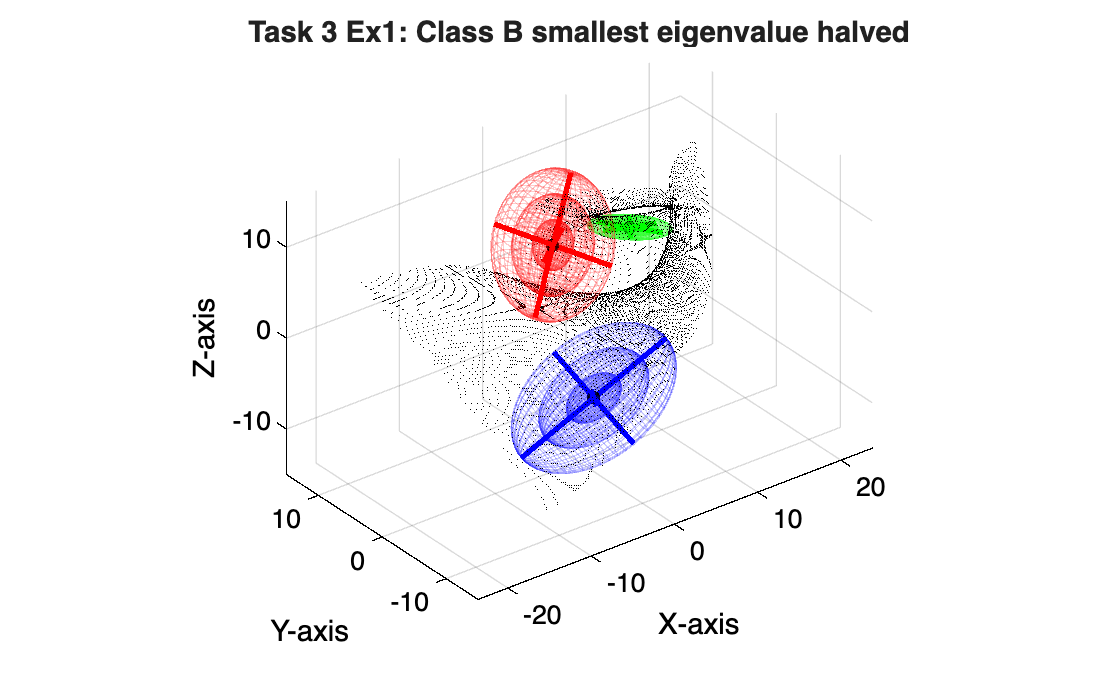

plotScenario(mu_a, covm_a, mu_b, covm_b_down, mu_c, covm_c, ...
    'Task 3 Ex1: Class B smallest eigenvalue halved', Vaxis, Num);



% Example 2: Double the smallest eigenvalue of B (0.25 -> 0.50)
D_b_up = D_b;
D_b_up(1,1) = 0.25 * 2.0; % 100% increase (tiny absolute change of 0.25)
covm_b_up = V_b * D_b_up * V_b';
fprintf('Example 2: smallest eigenvalue doubled: 0.25 -> 0.50\n');

Example 2: smallest eigenvalue doubled: 0.25 -> 0.50


fprintf('  Precision shifts: %.4f -> %.4f (Halves!)\n\n', 1/0.25, 1/0.50);

  Precision shifts: 4.0000 -> 2.0000 (Halves!)



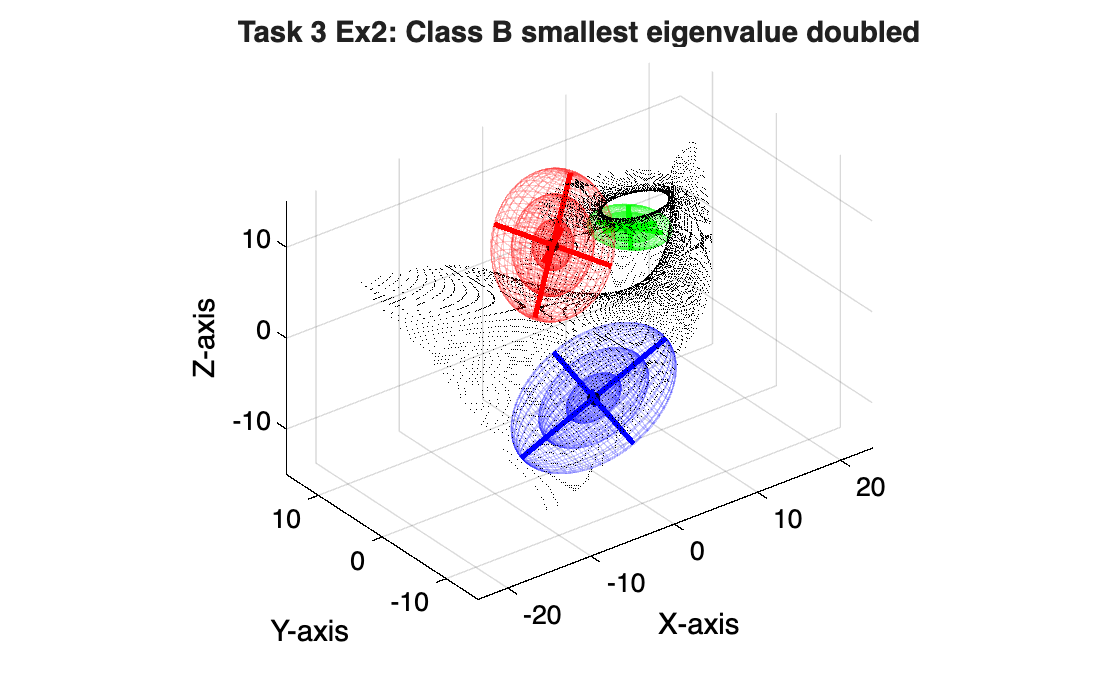

plotScenario(mu_a, covm_a, mu_b, covm_b_up, mu_c, covm_c, ...
    'Task 3 Ex2: Class B smallest eigenvalue doubled', Vaxis, Num);

By making these small changes to the smallest eigenvector for class B, we change the orientation of the tube-shaped boundaries around class B by large amount, flattening the tube in one dimension in the first case and making it larger and more concentric in the second.

% task 4
function [bAB, bAC, bCB] = computeBoundariesWithPriors(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, Vaxis, Num, P)
    grid_points = vol3D(Vaxis, Num);

    covm_a_inv = inv(covm_a); covm_b_inv = inv(covm_b); covm_c_inv = inv(covm_c);
    covm_a_det = det(covm_a); covm_b_det = det(covm_b); covm_c_det = det(covm_c);

    cp_a = grid_points - mu_a; cp_b = grid_points - mu_b; cp_c = grid_points - mu_c;

    % Bayesian discriminant scores (using incoming variable vector P)
    g_a = -0.5 * sum((cp_a * covm_a_inv) .* cp_a, 2) - 0.5 * log(covm_a_det) + log(P(1));
    g_b = -0.5 * sum((cp_b * covm_b_inv) .* cp_b, 2) - 0.5 * log(covm_b_det) + log(P(2));
    g_c = -0.5 * sum((cp_c * covm_c_inv) .* cp_c, 2) - 0.5 * log(covm_c_det) + log(P(3));

    epsilon = 0.05;
    bAB = grid_points((abs(g_a - g_b) < epsilon) & (g_a > g_c) & (g_b > g_c), :);
    bAC = grid_points((abs(g_a - g_c) < epsilon) & (g_a > g_b) & (g_c > g_b), :);
    bCB = grid_points((abs(g_b - g_c) < epsilon) & (g_b > g_a) & (g_c > g_a), :);
end

function plotScenarioWithPriors(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, titleStr, Vaxis, Num, P)
    [bAB, bAC, bCB] = computeBoundariesWithPriors(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, Vaxis, Num, P);
    colors = {'r', 'g', 'b'};
    figure; set(gcf, 'Color', 'w'); clf; hold on; grid on; axis equal; view(3);
    set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k');
    
    plotClassEllipsoids(mu_a, covm_a, colors{1});
    plotClassEllipsoids(mu_b, covm_b, colors{2});
    plotClassEllipsoids(mu_c, covm_c, colors{3});
    
    plot3(bAB(:,1), bAB(:,2), bAB(:,3), 'k.', 'MarkerSize', 1);
    plot3(bAC(:,1), bAC(:,2), bAC(:,3), 'k.', 'MarkerSize', 1);
    plot3(bCB(:,1), bCB(:,2), bCB(:,3), 'k.', 'MarkerSize', 1);
    title(titleStr); xlabel('X-axis'); ylabel('Y-axis'); zlabel('Z-axis'); hold off;
end

Q4: Adding in prior probabilities for each of the three classes has a huge effect on the boundaries. If a prior probability is very large for a class, then that class's boundary will expand relative to the others. We do this for class A, inflating its prior probability to 80% in case 4A. We then run case 4B, where we lower the prior probability of class B to 2%. In this final case, the class B boundary shrinks back, with the "cylinder" region near class A and C swallowed up, producing two distant conical regions for class B further out.

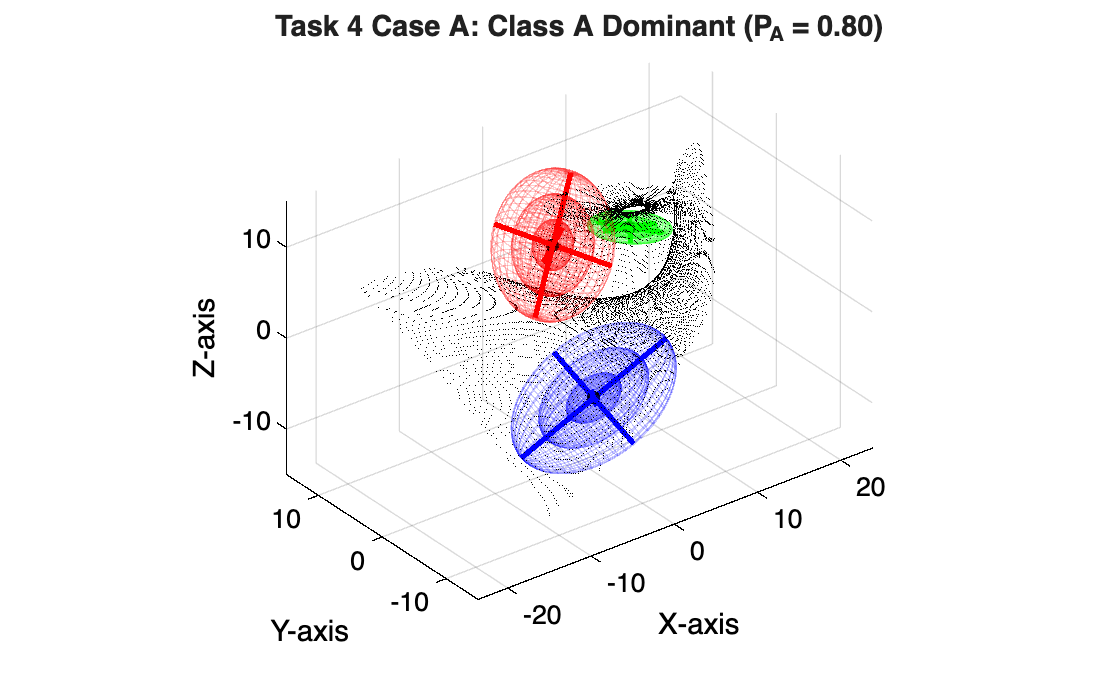

% TASK 4: A Priori Probability Variations

% Case 4A: Class A is highly dominant (e.g., 80% of all occurrences)
P_dominant_A = [0.80, 0.10, 0.10];
plotScenarioWithPriors(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, ...
    'Task 4 Case A: Class A Dominant (P_A = 0.80)', Vaxis, Num, P_dominant_A);

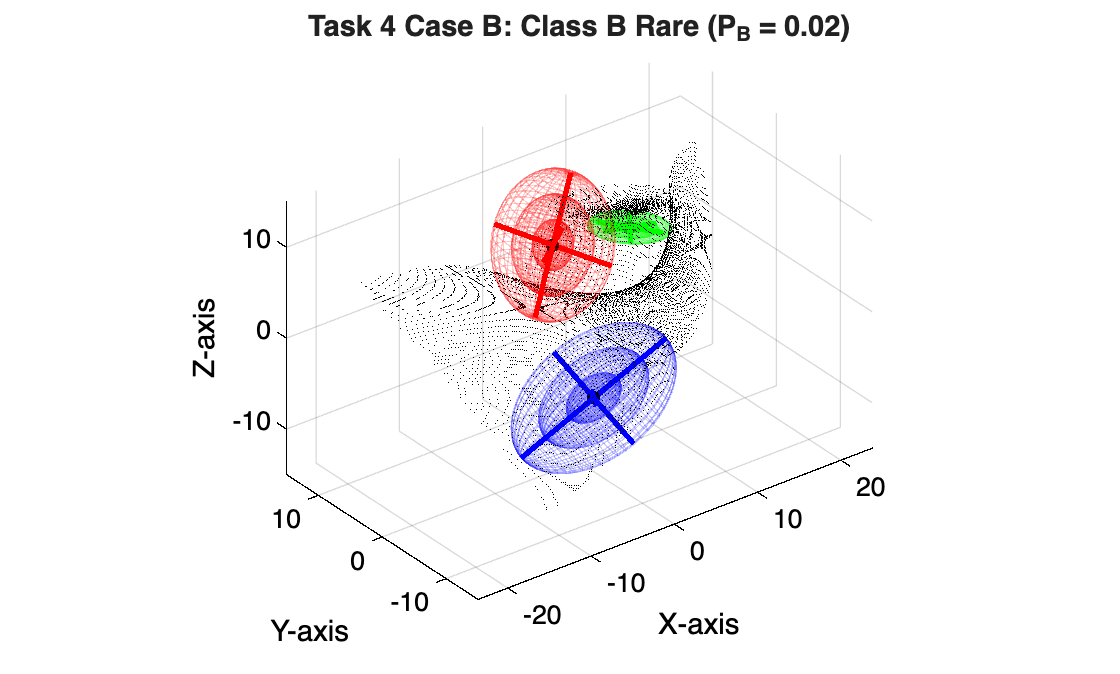


% Case 4B: Class B is extremely rare (only 2% occurrence)
P_rare_B = [0.49, 0.02, 0.49];
plotScenarioWithPriors(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, ...
    'Task 4 Case B: Class B Rare (P_B = 0.02)', Vaxis, Num, P_rare_B);

% task 5
function [bAB, bAC, bCB] = computeRiskBoundaries(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, Vaxis, Num, Lambda, P)
    grid_points = vol3D(Vaxis, Num);
    N_pts = size(grid_points, 1);

    % Compute the pure multivariate normal probabilities (likelihoods) for each grid point
    % mvnpdf gets true densities
    prob_a = mvnpdf(grid_points, mu_a(:)', covm_a);
    prob_b = mvnpdf(grid_points, mu_b(:)', covm_b);
    prob_c = mvnpdf(grid_points, mu_c(:)', covm_c);

    % Joint probabilities: p(x, omega_j) = p(x|omega_j) * P(omega_j) --
    % multiply likelihood by prior for each class
    joint_a = prob_a * P(1);
    joint_b = prob_b * P(2);
    joint_c = prob_c * P(3);

    % Calculate total conditional risk for taking action alpha_1, alpha_2, or alpha_3
    % R(alpha_i | x) = lambda_ia*joint_a + lambda_ib*joint_b + lambda_ic*joint_c
    Risk_A = Lambda(1,1)*joint_a + Lambda(1,2)*joint_b + Lambda(1,3)*joint_c;
    Risk_B = Lambda(2,1)*joint_a + Lambda(2,2)*joint_b + Lambda(2,3)*joint_c;
    Risk_C = Lambda(3,1)*joint_a + Lambda(3,2)*joint_b + Lambda(3,3)*joint_c;

    % Convert minimizing risk into maximizing negative risk:
    % Use logarithmic scale to fix the boundary thickness
    % (Adding realmin prevents log(0) errors in the far empty corners of the grid)
    g_a = -log(Risk_A + realmin);
    g_b = -log(Risk_B + realmin);
    g_c = -log(Risk_C + realmin);

    % Now we can use the same epsilon from Tasks 1-4
    epsilon = 0.05;
    bAB = grid_points((abs(g_a - g_b) < epsilon) & (g_a > g_c) & (g_b > g_c), :);
    bAC = grid_points((abs(g_a - g_c) < epsilon) & (g_a > g_b) & (g_c > g_b), :);
    bCB = grid_points((abs(g_b - g_c) < epsilon) & (g_b > g_a) & (g_c > g_a), :);
end

function plotRiskScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, titleStr, Vaxis, Num, Lambda, P)
    [bAB, bAC, bCB] = computeRiskBoundaries(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, Vaxis, Num, Lambda, P);
    colors = {'r', 'g', 'b'};
    figure; set(gcf, 'Color', 'w'); clf; hold on; grid on; axis equal; view(3);
    set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k');
    
    plotClassEllipsoids(mu_a, covm_a, colors{1});
    plotClassEllipsoids(mu_b, covm_b, colors{2});
    plotClassEllipsoids(mu_c, covm_c, colors{3});
    
    plot3(bAB(:,1), bAB(:,2), bAB(:,3), 'k.', 'MarkerSize', 1);
    plot3(bAC(:,1), bAC(:,2), bAC(:,3), 'k.', 'MarkerSize', 1);
    plot3(bCB(:,1), bCB(:,2), bCB(:,3), 'k.', 'MarkerSize', 1);
    title(titleStr); xlabel('X-axis'); ylabel('Y-axis'); zlabel('Z-axis'); hold off;
end

Task 5: We created two cases to look at and our assessment follows each example below.

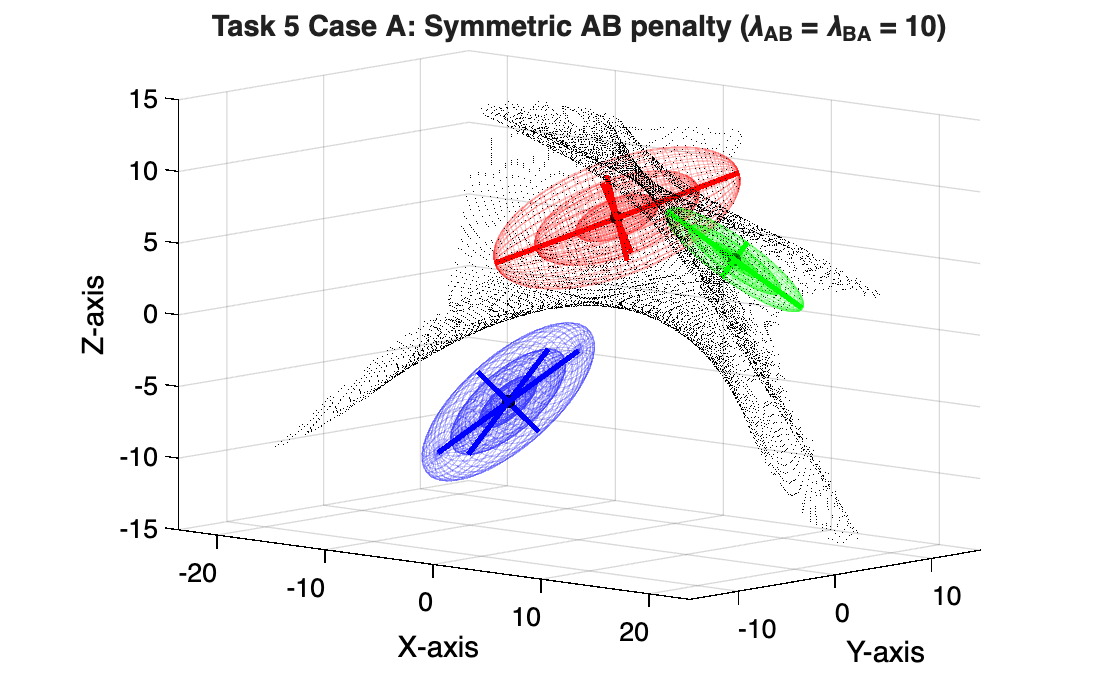

% %%% TASK 5: Risk / Loss Function Variations %%%
P_equal = [1/3, 1/3, 1/3];

% Baseline Zero-One Loss Matrix (equivalent to normal classification)
Lambda_zero_one = [0 1 1;
                   1 0 1;
                   1 1 0];

% Case 5A: Extreme penalty for confusing A and B
% (causes the boundary between A and B to distort near C)
Lambda_sym_AB = [0 10 1;
                  10 0 1;
                  1 1 0];
plotRiskScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, ...
    'Task 5 Case A: Symmetric AB penalty (\lambda_{AB} = \lambda_{BA} = 10)', Vaxis, Num, Lambda_sym_AB, P_equal);

Interestingly, there is a double cylinder forming around Class B here. This may be because the boundary between class A and B has such a high penalty for errors, that class C is actually chosen in certain cases near the A/B boundary, where it's not too close to A and not too close to B. It's possible to follow the boundary between class B and C into that region between A and B and see that this appears to be the case! So we are essentially choosing class C in cases where we normally wouldn't, just to avoid the massive penalty for an incorrect choice near the A/B class boundary.

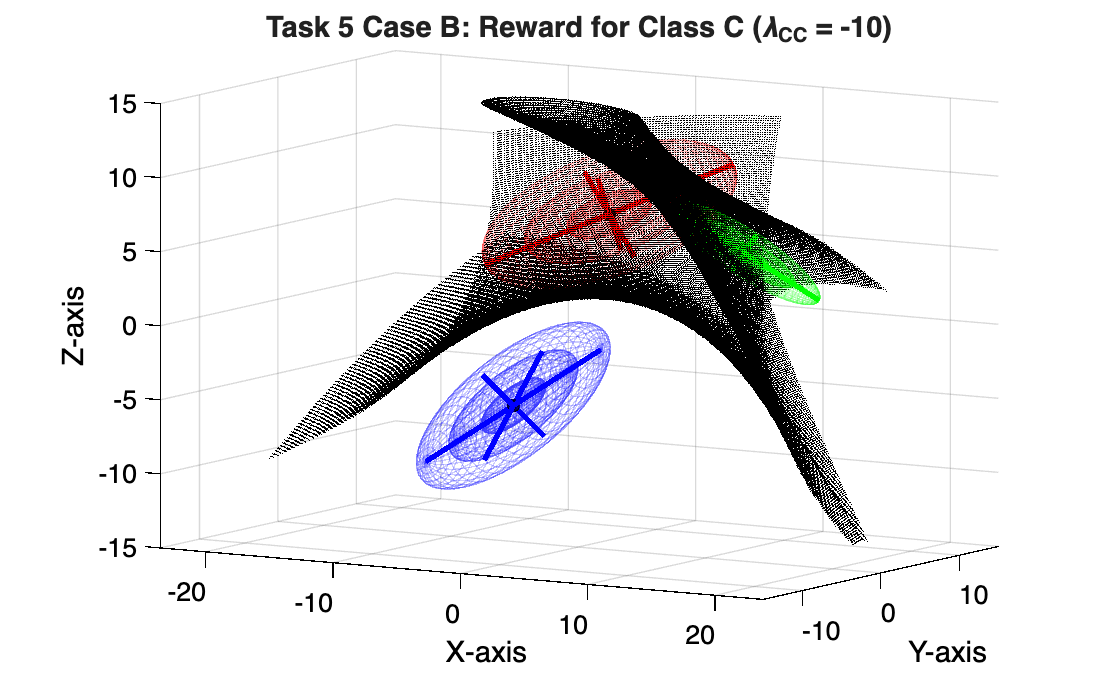

% Case 5B: Big reward for correctly identifying Class C
% Change is on the diagonal this time
Lambda_reward_C = [0  1  1;
    1  0  1;
    1  1 -10];
% Negative numbers created problems in our plot; adding ten to every
% element in the risk matrix fixed this
Lambda_reward_C = Lambda_reward_C + 10;
plotRiskScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, ...
    'Task 5 Case B: Reward for Class C (\lambda_{CC} = -10)', Vaxis, Num, Lambda_reward_C, P_equal);

Here, we see that class C's boundary expands outward when we apply a negative value for lambda_cc. A negative value for the cost of classifying C when the truth is C is the same as a reward for correctly classifying C. Therefore, we expect class C's boundary to expand. This effect is the same as when we increased the prior probability of class C.

Task 6: We choose class B since it had the biggest ratio between its smallest and largest eigenvalue. We can place an outlier along the direction of that smallest eigenvalue. We already noticed that distortions in that direction will have relatively large effects on the Gaussian distribution and boundaries for the class, so this is a good example to choose. Discussion is below the two examples.

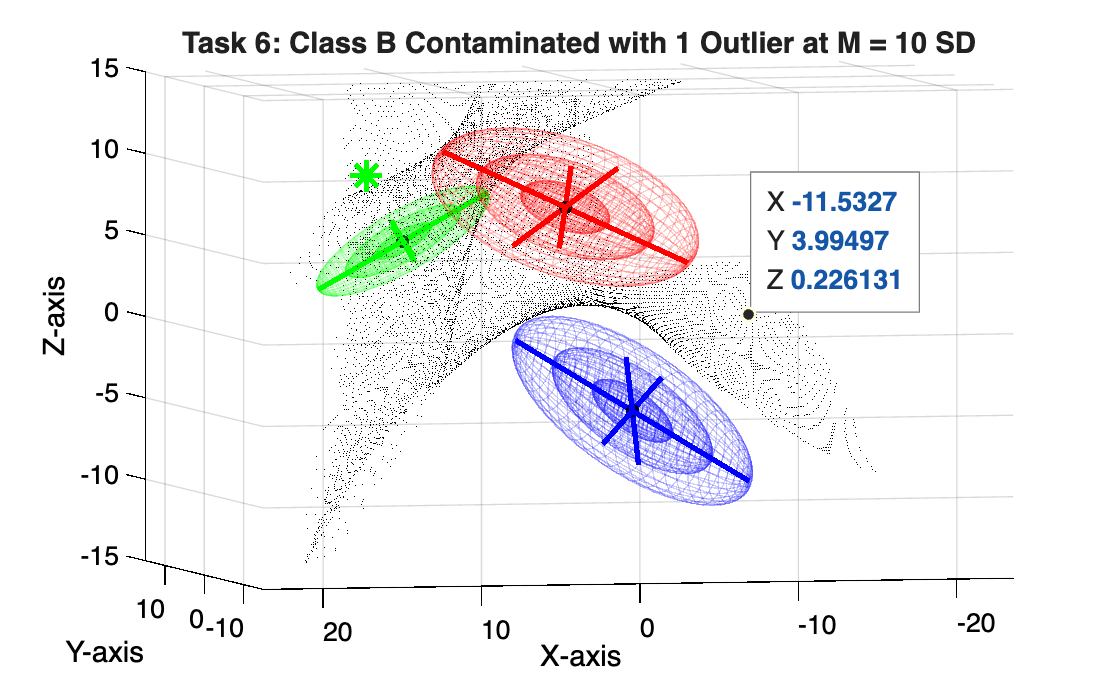

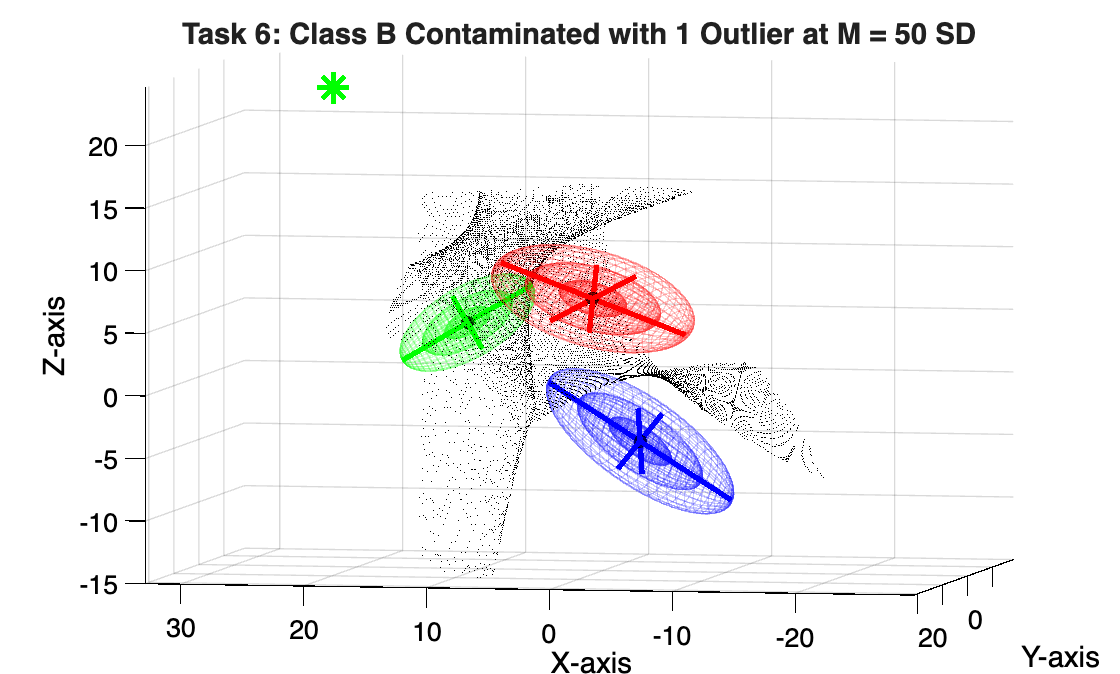

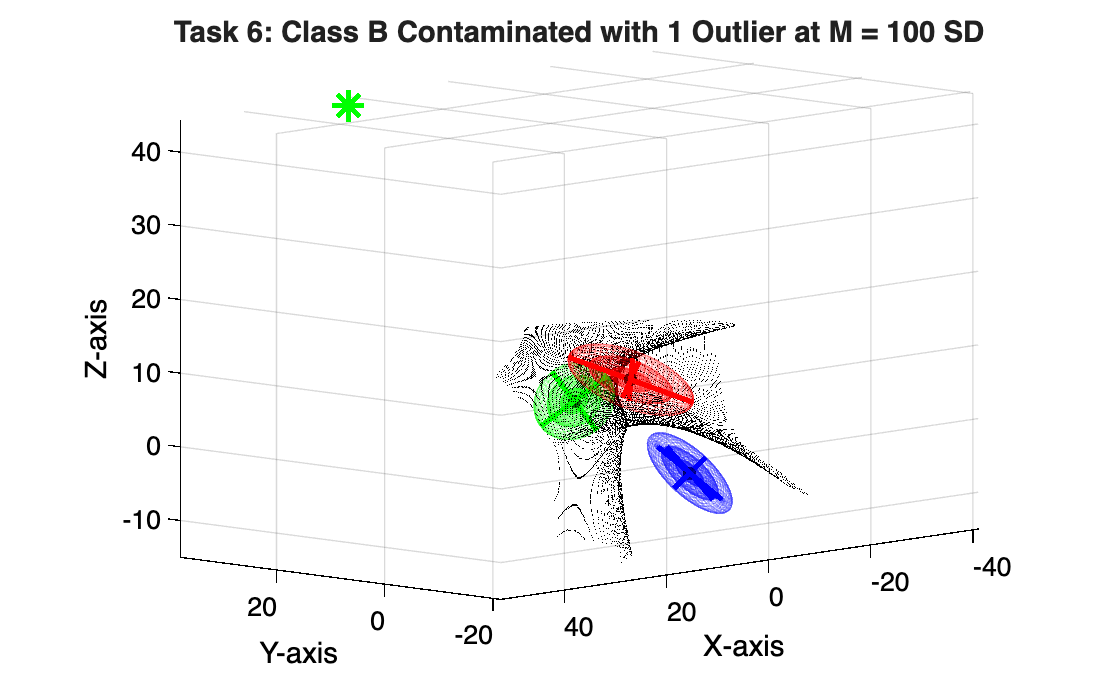

% Task 6

[V_b, D_b] = eig(covm_b);
radii_b = sqrt(diag(D_b));

% Choose the direction of Class B's most sensitive (smallest) eigenvalue
% axis
outlier_direction = V_b(:, 1)'; 

% Evaluate the impacts of 10, 50, and 100 standard deviations
mahalanobis_distances = [10, 50, 100];

for M = mahalanobis_distances
    % Calculate the exact 3D spatial coordinate of the single outlier
    single_outlier = mu_b + (M * radii_b(1)) * outlier_direction;
    
    % Create a contaminated version of Class B's data (1000 baseline points + 1 outlier)
    % Regenerate the exact baseline distribution and append the extreme outlier
    X_b_baseline = genExactGauss(1000, mu_b, covm_b);
    X_b_contaminated = [X_b_baseline; single_outlier];
    
    % Calculate the new empirical parameter estimations
    mu_b_contaminated = mean(X_b_contaminated);
    covm_b_contaminated = cov(X_b_contaminated);
    
    % Plot the distorted scenario using equal priors
    P_equal = [1/3, 1/3, 1/3];
    titleString = sprintf('Task 6: Class B Contaminated with 1 Outlier at M = %d SD', M);
    
    plotScenarioWithPriors(mu_a, covm_a, mu_b_contaminated, covm_b_contaminated, mu_c, covm_c, ...
        titleString, Vaxis, Num, P_equal);
    
    % Overlay the outlier coordinate on the active figure to see it explicitly
    hold on;
    plot3(single_outlier(1), single_outlier(2), single_outlier(3), 'g*', 'MarkerSize', 12, 'LineWidth', 2);
    hold off;
end

function X_m = genExactGauss(K, mu, covm)
    lenMu = length(mu);
    data = whitenData(K, lenMu);
    [V, D] = eig(covm);
    X_m = (data * sqrt(D) * V') + mu(:)'; 
end

function X_w = whitenData(K, dims)
    data = randn(K, dims);
    data = data - mean(data);
    [V, D] = eig(cov(data));
    X_w = data * V * inv(sqrt(D));
end

A single outlier has a huge impact on the boundaries of the class in some cases. In our case, we plotted outliers along the axis of the smallest eigenvector to highlight a worst case scenario, choosing Class B. Once the outlier was 100 standard deviations away, the boundary for Class B expanded outward, swallowing huge regions of classes A and C as it did so. This is an important result: It highlights just how big an impact an outlier can have for a Bayes decision boundary. It suggests that we may need to identify outliers and do something to prevent this possibility.

Task 7

(a) Yes. In parametric methods (like Gaussian Bayes Classifiers), a few extreme outliers heavily skew global statistics just as we saw in Task 6. In non-parametric methods (like Support Vector Machines or Nearest Neighbor models), the decision boundary is inherently local and can be positioned entirely based on individual edge cases or noisy samples near the class intersections.

(b) No, in general engineering contexts. A robust classification boundary should capture the underlying macroscopic distribution probability density of the phenomena, not localized noise or data collection anomalies. High sensitivity to a tiny fraction of data samples is the definition of overfitting and leads to models that perform poorly on fresh testing datasets.

The only time this sensitivity would be appropriate is in adversarial anomaly detection (e.g., credit card fraud or nuclear meltdown warning diagnostics), where a single outlier point genuinely represents a large system state shift.

(c) There are a few ways to detect anomalies: 

1. Statistical Distance Metrics: Compute the Mahalanobis Distance for every point during preprocessing. Any point exhibiting an unusually high distance value relative to a pre-defined threshold (chi-squared or something else) is a clear statistical anomaly. This is computationally expensive though.

2. Resampling and Cross-Validation Variance: Implement k-fold cross-validation or bootstrapping. If the decision boundary shape or model accuracy shifts erratically when a few samples are excluded from a training fold, the model is overly sensitive to those specific points, and they can be removed.

3. Isolation forest anomaly detection; this was my final project topic last semester in CSC 502. It saves computation as it finds outliers via an isolation forest decision tree structure. Anomalies tend to be separated early when making random branches on random features (this fact allows this method to save computation time - no need to measure distances between data points). Measuring the number of nodes between the root to the leaf in the tree (path length) can lead to a measure of likelihood that a data point is an outlier.

(d) There are many ways to remove outliers; here are a few we could use:

1. Use a strict Mahalanobis distance or Isolation Forest filter to prune out extreme points before fitting your Gaussian models. Isolation forest does have some requirements on the data and feature structure, so this would need to be studied first before it could be used reliably. In our project work, we found a problematic bias whenever data is not evenly or symmetrically distributed across the whole range of values on a feature for example; in this case, that should be fine since our data points are defined by Gaussian distributions though!

2. We could also use Robust Estimators: Instead of using standard maximum likelihood estimation (`mean()` and `cov()`), estimate your parameters using robust alternatives such as the Minimum Covariance Determinant (MCD) or Huber M-estimators, which automatically down-weight or ignore severe outliers.

3. Regularization: Apply a regularized covariance architecture (e.g., adding a small ridge value to the diagonal), which penalizes volatile, uncharacteristic covariance inflations.